# Microwave Engineering Lab. FMCW Radar.- Northe, Velez, Woerner

## Preparation for the experiment

### Question 1: Doppler Frequency

Assuming a car moving along x axis at the velocity v = 75 km/h , and the radar with a beamwidth of $ \theta$ = 30º captures the car when it moves from x = 37m to x = 10m. The geometry of the radar and car is illustrated in the following figure. The frequency is 24 GHz.

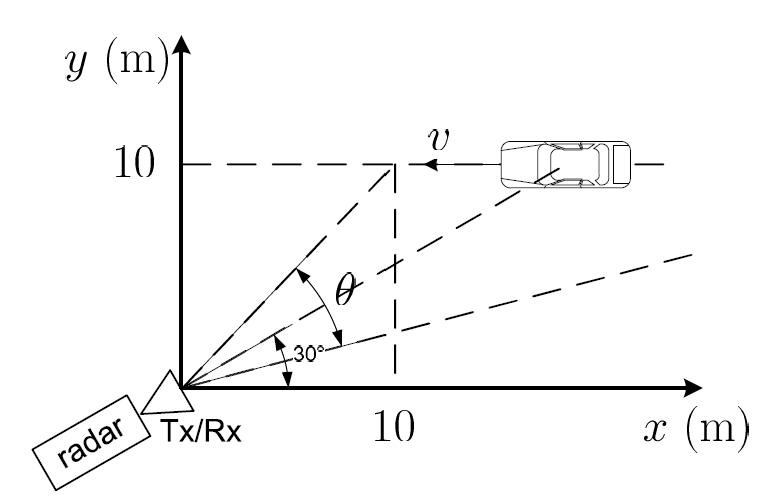

Calculate the distance between the radar and the car depending on the time (R(t)). Write down

the expression of the Doppler frequency caused by the moving car, and draw the fD (t) curve

using MATLAB ($t=0$ when $x_{car}=10$). Attach the source code!

#### Answer:


$$R(t) = \sqrt{x^2 + y^2}=\sqrt{(10+v_{car} \ t)^2+100}$$



$$f_D = 2 \frac{v_{car}}{\lambda} \cos \alpha$$


Where $\alpha$ is the angle of attack.

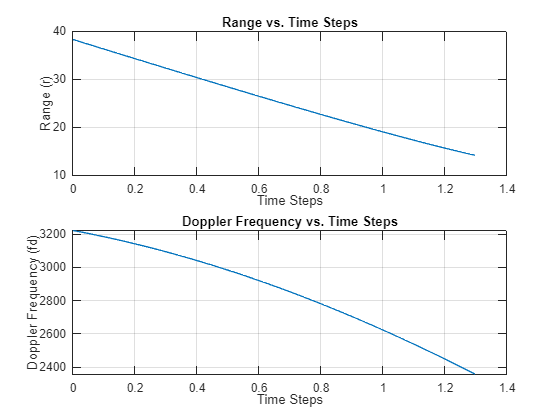

clear; close all; clc;

% Consts
c0 = physconst('LightSpeed');

% some helper functions
kmh_to_ms   = @(kmh) kmh / 3.6;
f_2_lambda  = @(f) c0 / f;
calc_fd     = @(vr, lambda, aoa) 2 * vr / lambda * cos(aoa);

% define vars
fc          = 24e9;           % [Hz]
v_target    = kmh_to_ms(75);  % [m/s]
beamwidth   = 30;             % [deg]
start_aoa   = 15;             % [deg]; aoa = Angle of Attack
x_start     = 37;             % [m]
x_end       = 10;             % [m]
y_pos       = 10;             % [m]


lambda = f_2_lambda(fc);
delta_s = (x_end - x_start);
delta_t = abs(delta_s) / v_target;

n_steps = 100;
time_steps = linspace(0, delta_t, n_steps);
r = zeros(1, n_steps);
fd = zeros(1, n_steps);

% if it wouldn't be already in the diagram we could use arctan(y / x)
aoa = linspace(start_aoa, beamwidth + start_aoa, n_steps);

for t = 1:length(time_steps)
    x_pos = x_start - time_steps(t) * v_target;
    r(t) = sqrt(y_pos^2 + x_pos^2);
    fd(t) = calc_fd(v_target, lambda, deg2rad(aoa(t)));
end


figure;
subplot(2, 1, 1);
plot(time_steps, r);
xlabel('Time Steps');
ylabel('Range (r)');
title('Range vs. Time Steps');
grid on;

subplot(2, 1, 2);
plot(time_steps, fd);
xlabel('Time Steps');
ylabel('Doppler Frequency (fd)');
title('Doppler Frequency vs. Time Steps');
grid on;

### Question 2: Signal to Noise Ratio

Assuming a triangular trihedral with the length of side a = 0:25m put 3 m away in front of the

radar, the A/D sampling rate is 100 kHz, f is 24 GHz. Calculate the SNR of the output signal of

AD converter, values of parameters shown in the following figure and table.

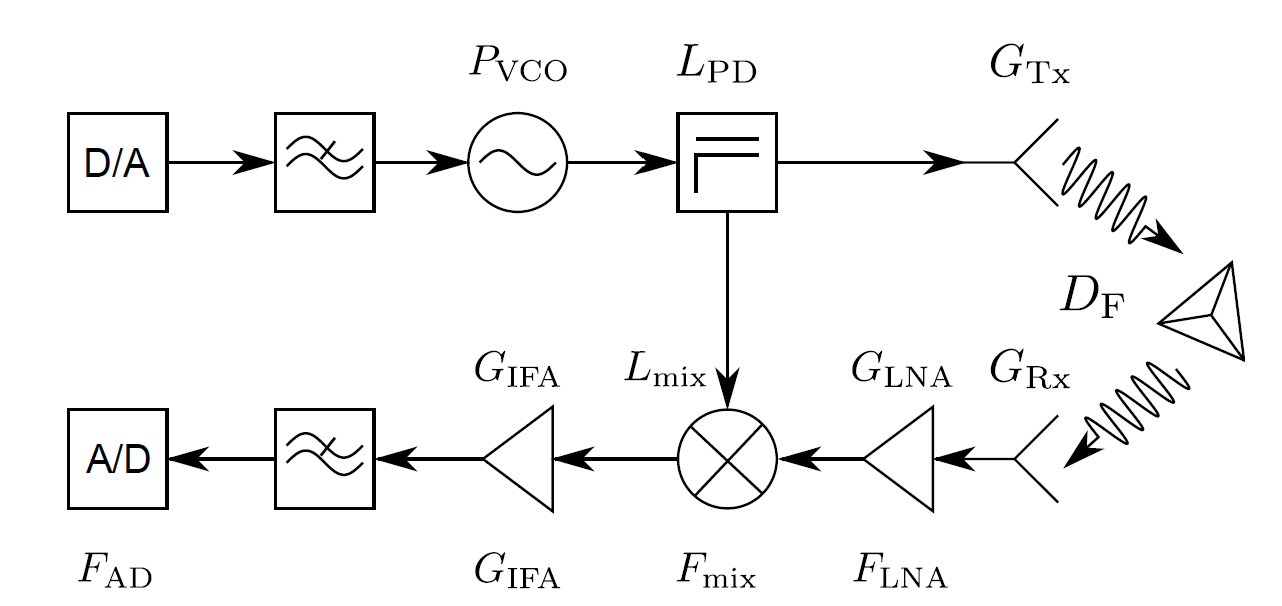

clear; close all; clc;

c0 = physconst('LightSpeed');
k_b = physconst('Boltzmann');

db_2_lin    = @(g) 10^(g / 10);
dbm_2_lin = @(g) 10.^((g - 30) / 10);

lin_2_db    = @(g) 10 * log10(g);
lin_2_dBm   = @(g) lin_2_db(g) + 30;

f_2_lambda  = @(f) c0 / f;

T       = 290;           % [K]
fc      = 24e9;          % [Hz]
fs      = 100e3;         % [Hz]
r       = 3;             % [m]
a       = 0.25;          % [m]
P_vco   = 12;            % [dBm]
L_pd    = 4;             % [dB]
G_ant   = 15;            % [dBi]
G_lna   = 18;            % [dB]
L_mix   = 8;             % [dB]
G_ifa   = 33.3;          % [dB]
F_lna   = 2.6;           % [dB]
F_mix   = 8;             % [dB]
F_ifa   = 19.1;          % [dB]
F_ad    = 59;            % [dB]


lambda = f_2_lambda(fc);
rcs = 4 * pi * a^4 / (3 * lambda^2)

rcs = 104.8648

D_f = lin_2_db((4 * pi)^3 * r^4 / (rcs * lambda^2))

D_f = 69.9227

P_in  = P_vco - L_pd + G_ant - D_f + G_ant

P_in = -31.9227

N_t   = lin_2_dBm(k_b * T * fs)

N_t = -123.9752

SNR_i = P_in - N_t

SNR_i = 92.0525

NF = F_lna +...
       (F_mix - 1) / G_lna +...
       (F_ifa - 1) / (G_lna * L_mix) +...
       (F_ad  - 1) / (G_lna * L_mix * G_ifa)

NF = 3.1267

SNR_o = SNR_i - NF

SNR_o = 88.9258

### Question 3: Signal Form

The FMCW mechanism cannot only be applied on a radar, but also on an ultrasound sensor. Assuming

that an FMCW ultrasound sensor with triangular modulation is used for distance measurement,

whose parameters are listed in the following table.

#### 1.- Write down the expressions:

The expressions for the transmitted RF signal in time domain are:


$$s_{t,up}(t) =A_t\cos \left( 2\pi f_{\min} \hat{t} + \pi \gamma \hat{t}^2 \right)  = \cos \left( 2\pi 20kHz \hat{t} + \pi \gamma \hat{t}^2 \right)$$



$$s_{t,down}(t) = A_t \cos \left( 2\pi f_{\max} \hat{t} - \pi \gamma \hat{t}^2 \right)  = \cos \left( 2\pi 40kHz \hat{t} - \pi \gamma \hat{t}^2 \right)$$



$$s_r(t) =

\begin{cases}

A_r \cos \left[ 2\pi f_{\min} \left(\hat{t} - \tau\right) + \pi \gamma \left( \hat{t} - \tau \right)^2 \right] & 2nT_{\text{sweep}} \leq t < (2n+1)T_{\text{sweep}} \\

A_r \cos \left[ 2\pi f_{\max} \left(\hat{t} - \tau\right) - \pi \gamma \left( \hat{t} - \tau \right)^2 \right] & (2n+1)T_{\text{sweep}} \leq t < 2(n+1)T_{\text{sweep}}

\end{cases}$$


Substituting the problem values:


$$s_r(t) =

\begin{cases}

\cos \left[ 2\pi 20kHz \left(\hat{t} - 5.8ms \right) + \pi \gamma \left( \hat{t} -  5.8ms \right)^2 \right] & 2n200ms \leq t < (2n+1)200ms \\

\cos \left[ 2\pi 40kHz \left(\hat{t} -  5.8ms\right) - \pi \gamma \left( \hat{t} -  5.8ms \right)^2 \right] & (2n+1)200ms \leq t < 2(n+1)200ms

\end{cases}$$


#### 2.- Generate and plot sr(t)

Plot $s_r(t) $ for one period in Matlab.

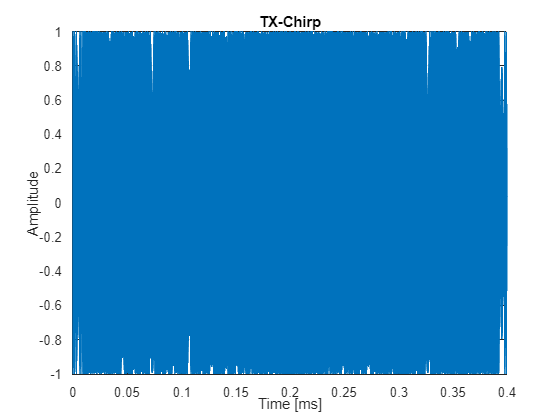

clear; close all; clc;

% Parameters
c_s         = 345;            % [m/s]
f_c         = 30e3;           % Carrier frequency [Hz]
B           = 20e3;           % Bandwidth [Hz]
T_sweep     = 200e-3;         % Total duration [s]
distance    = 1;              % [m]

delta_t = 2 * distance / c_s;

steps = 16 * 1024;
time_per_step = 2 * T_sweep / steps;
t = linspace(0, 2 * T_sweep, steps);

up = chirp(t(1:steps/2), f_c - B/2, T_sweep, f_c + B/2, 'linear');

down = chirp(t(1:steps/2), f_c + B/2, T_sweep, f_c - B/2, 'linear');

s_t = [up, down];

n_samples_shifted = round(delta_t / time_per_step);
s_r = [zeros(1, n_samples_shifted), s_t];

% match length of input vector -> append samples from the following sweep
s_t_mp = [s_t, s_t(1:n_samples_shifted)];

% Plot
figure(1)
plot(t, s_t)
xlabel('Time [ms]')
ylabel('Amplitude')
title('TX-Chirp')
grid on

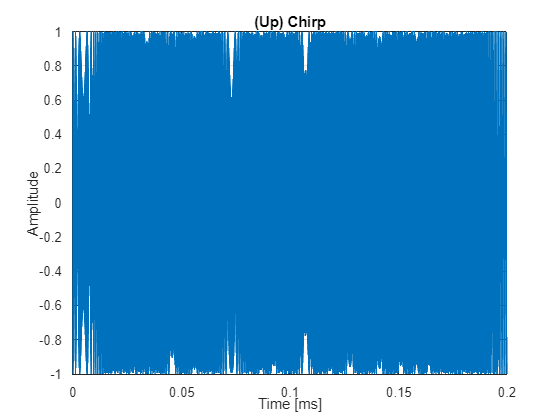

figure(2)
plot(t(1:steps/2), up)
xlabel('Time [ms]')
ylabel('Amplitude')
title('(Up) Chirp')
grid on

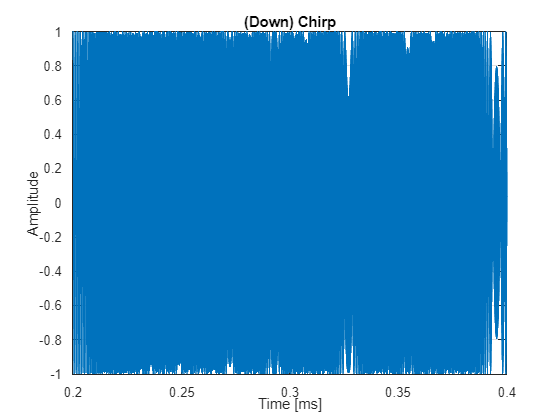

figure(3)
plot(t(steps/2 +1 : end), down)
xlabel('Time [ms]')
ylabel('Amplitude')
title('(Down) Chirp')
grid on

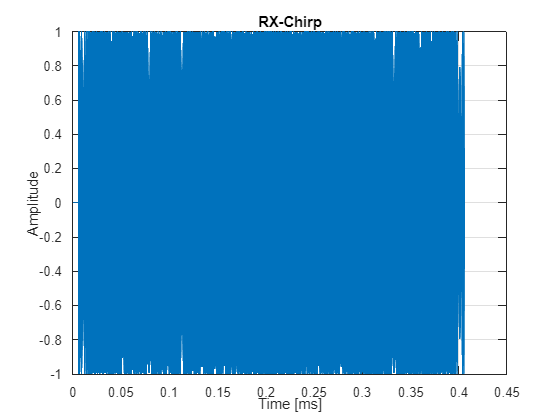

figure(4)
t_rx = linspace(0, 2 * T_sweep + delta_t, steps + n_samples_shifted);
plot(t_rx, s_r)
xlabel('Time [ms]')
ylabel('Amplitude')
title('RX-Chirp')
grid on

#### 3.- Generate the IF signal according to the mechanism of an ideal mixer and plot it for one period.

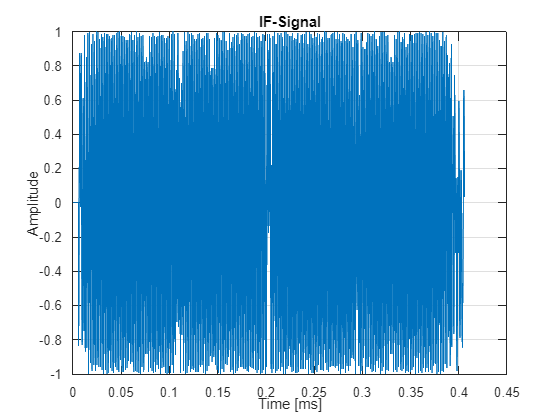

s_if = s_t_mp.*s_r;

figure(5)
plot(t_rx, s_if)
xlabel('Time [ms]')
ylabel('Amplitude')
title('IF-Signal')
grid on

### Question 4: Range and Velocity Measurement

An FMCW radar with triangular modulation is used for baseball training, the parameters of the

radar and the ball are given in the following table.

#### 1.- Write down the expression of the dechirped IF signal and plot it in time domain.

The expression, according to equation 1.15 provided in the document is:


$$s_{IF}(t)=\begin{cases}
\cos(2\pi f_1 t), & \text{if } 0 \leq t \leq T_{\text{sweep}} \\
\cos(2\pi f_2 t), & \text{if } T_{\text{sweep}} < t \leq 2T_{\text{sweep}}
\end{cases}$$


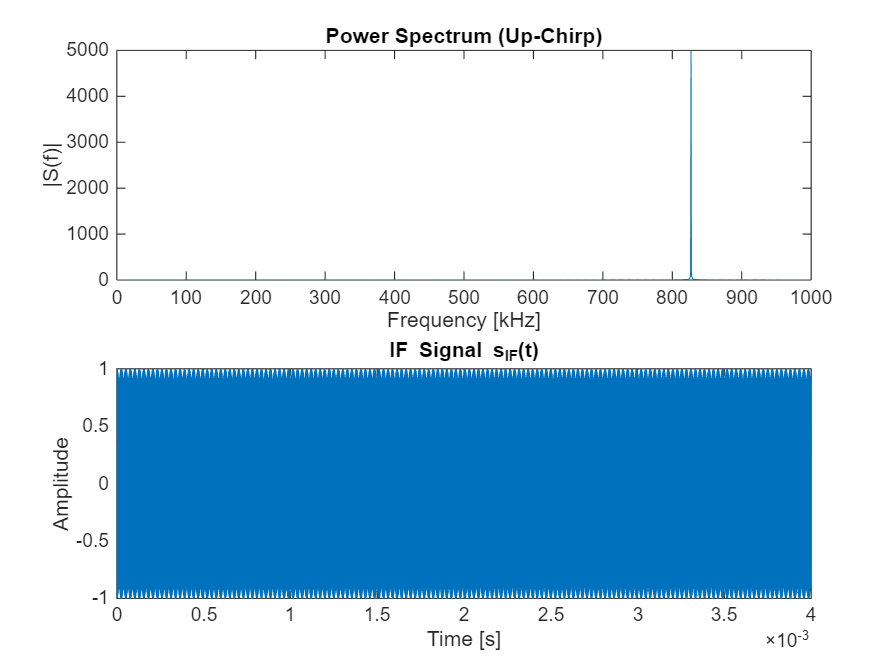

clear; clc;

% Parameters
f0 = 24e9;             % Hz
B = 1e9;               % Hz
Tsweep = 2e-3;         % s
c = 3e8;               % m/s
r = 250;               % m
vr = 40;               % m/s
fs = 5e6;              % sampling rate

t = 0:1/fs:2*Tsweep;   % simulate up + down sweep
gamma = B / Tsweep;

% Compute delays
tau = 2 * r / c;
fd = 2 * vr * f0 / c;

% Frequencies
fB = gamma * tau;
f1 = fB - fd;  % up-sweep
f2 = fB + fd;  % down-sweep

% Create IF signal
sIF = [cos(2*pi*f1*t(t <= Tsweep)), cos(2*pi*f2*t(t > Tsweep))];

% Plot
plot(t, sIF);
xlabel('Time [s]');
ylabel('Amplitude');
title('IF Signal s_{IF}(t)');

Now for obtaining the power spectrum to obtain the target's range and velocity:

% Extract segments
s_up = sIF(1:length(t)/2);

s_down = sIF(length(t)/2+1:end);

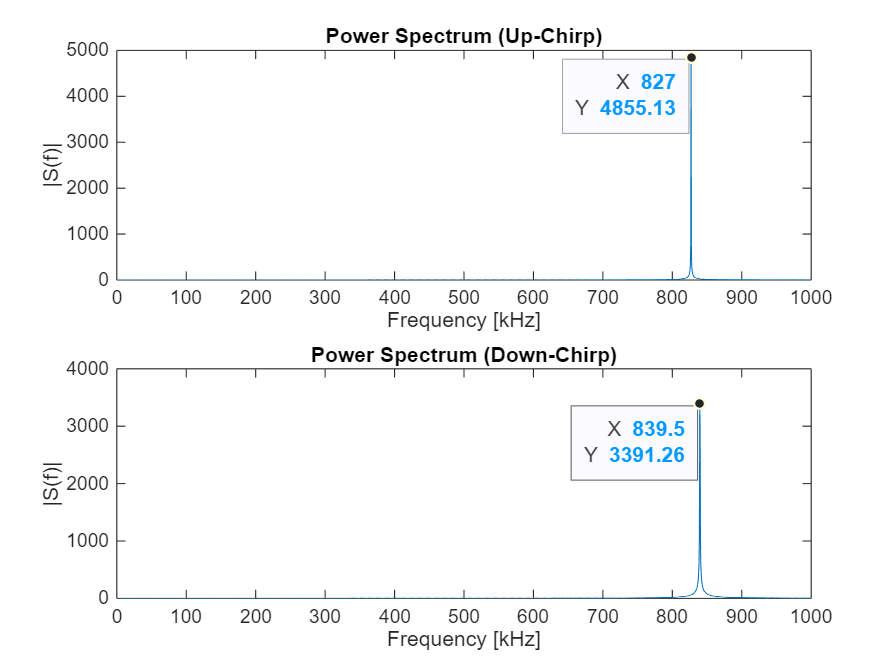

% FFT
N = length(s_up);
f = (0:N-1)*(fs/N);

S_up = abs(fft(s_up));
S_down = abs(fft(s_down));

% Plot
figure;
subplot(2,1,1);
plot(f/1e3, S_up);
title('Power Spectrum (Up-Chirp)');
xlabel('Frequency [kHz]'); ylabel('|S(f)|');
xlim([0 1000]);

subplot(2,1,2);
plot(f/1e3, S_down);
title('Power Spectrum (Down-Chirp)');
xlabel('Frequency [kHz]'); ylabel('|S(f)|');
xlim([0 1000]);

subplot(2,1,1)
ax = gca;
chart = ax.Children(1);
datatip(chart,827,4855);
subplot(2,1,2)
ax = gca;
chart = ax.Children(1);
datatip(chart,839.5,3391);

From the power spectrum plots, it is possible to directly extract the values for f1 and f2:


$$f_1 = 827 \ kHz$$



$$f_2 = 839.5 \ kHz$$


Now it is possible to directly compute the range and velocity of the target by using the formulas:

%From the spectrum plots f1 and f2 are estimated:

f1_est = 827e3;    % Estimated beat frequency during up-sweep
f2_est = 839e3;  % Estimated beat frequency during down-sweep

% Estimate range and velocity
fB_est = (f1_est + f2_est) / 2;
fd_est = (f2_est - f1_est) / 2;

range_est = (c / (2 * gamma)) * fB_est;
velocity_est = (c / (2 * f0)) * fd_est;

% Display results
fprintf('Estimated Range: %.2f m\n', range_est);

Estimated Range: 249.90 m


fprintf('Estimated Velocity: %.2f m/s\n', velocity_est);

Estimated Velocity: 37.50 m/s


#### 3.- Calculate the range resolution and the velocity resolution respectively:

delta_r = c / (2 * B);   % Range resolution in meters
fprintf('Range Resolution: %.3f meters\n', delta_r);

Range Resolution: 0.150 meters


delta_v = c / (2 * f0 * Tsweep);  % Velocity resolution in m/s
fprintf('Velocity Resolution: %.3f m/s\n', delta_v);

Velocity Resolution: 3.125 m/s
